defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 2 - ISCs']);

%parameters for analysis
peakProminenceThr = 25; %threshold in pA
conditions = {'Baseline','+MRS2500','+PPADS'};
conditionTimes = [0 300 480 780 960 1260; %150219_A1P1
                  300 600 900 1200 1380 1680; %150306_A1P1
                  300 600 900 1200 1380 1680; %150306_A2P1
                  15 314 660 960 1085 1385; %150306_A3P1
                  60 360 675 975 1290 1590; %150306_A4P1
                  15 315 615 915 1230 1530; %150308_A1P1
                  15 315 615 915 1230 1530; %150308_A2P1
                  0 300 600 900 1200 1500; %15503004
                  0 300 600 900 1200 1500]; %15503009

%%dir 
dname = '.\Data\WT_MRS_PPADS_RT';
if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end
analyze = [1 1 1]

analyze =      1     1     1


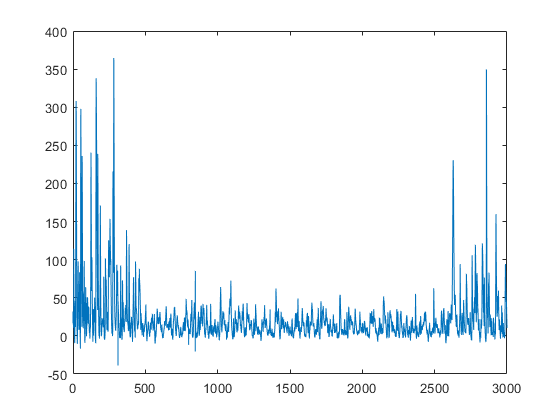

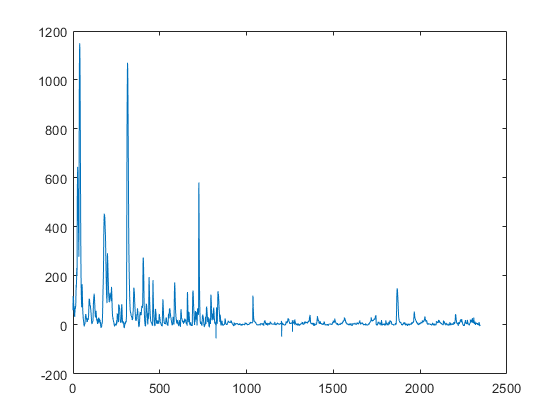

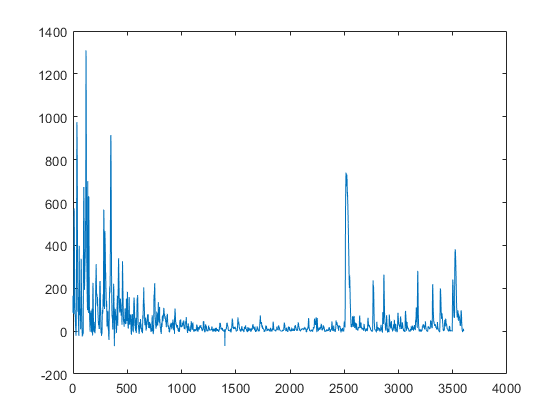

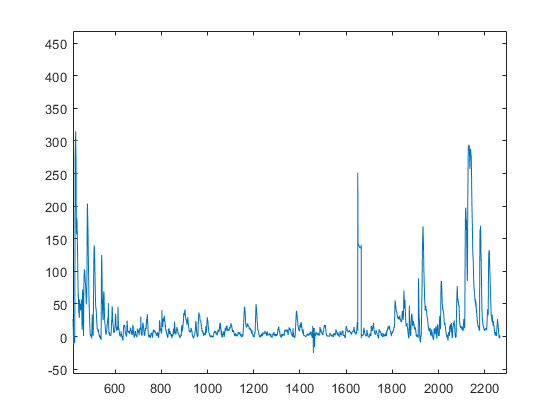

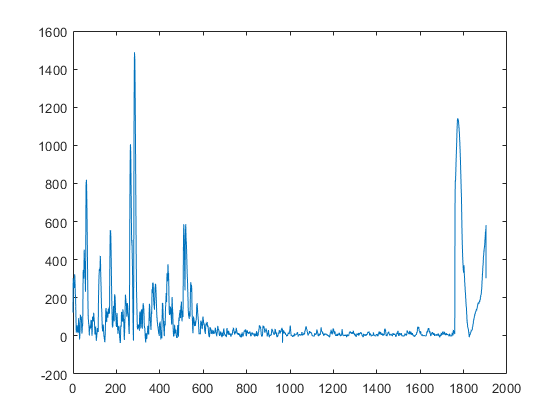

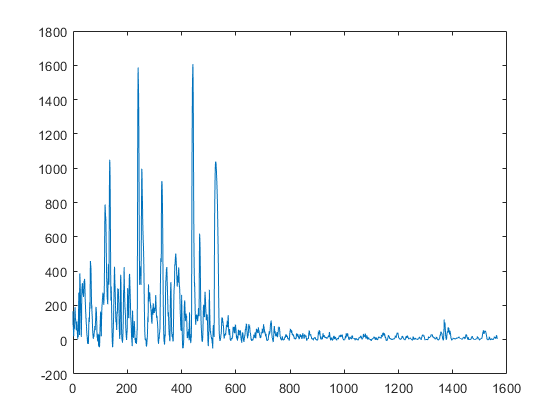

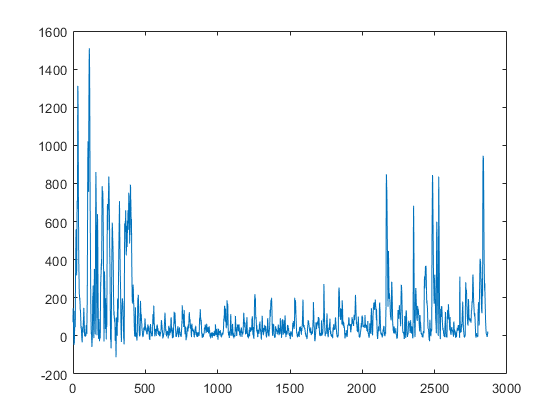

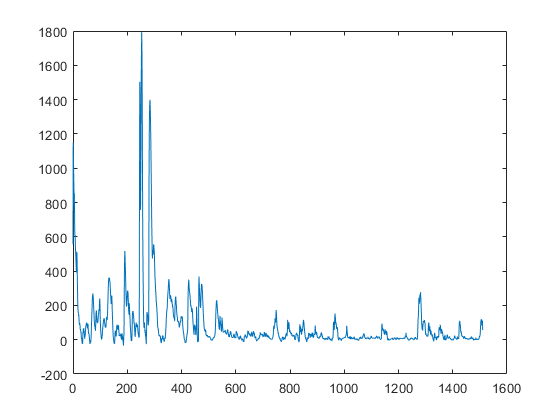

fileList = loadFileList([dname '\*_WT_MRS_PPADS.abf']);
for i = 1:size(fileList,1)

    if analyze(3) 
        [d,time,SR] = loadPclampData(fileList{i});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        figure; plot(time,out);
        % hold on;
%        plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditions,2)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(i,j+(j-1)*1) & locs < conditionTimes(i,j+(j-1)*1+1)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(i,j+(j-1)*1) & locs < conditionTimes(i,j+(j-1)*1+1)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(i,j+(j-1)*1) & time < conditionTimes(i,j+(j-1)*1+1)), ... 
                                     out(time > conditionTimes(i,j+(j-1)*1) & time < conditionTimes(i,j+(j-1)*1+1)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;
        tempCell = cellS(i);
        [d,f,ext] = fileparts(fileList{i});
        save([d '\' f '_stats.mat'],'tempCell')
    end
end

%
cellS = loadCellStructs('.\Data\WT_MRS_PPADs_RT\*_stats.mat')

cellS = 1×9 struct array with fields:
    rawLocPk
    stats


conditions = {'Baseline','+MRS2500','+PPADS'};


pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
h = compare2P(pkstatBlock(:,1),pkstatBlock(:,2),conditions(1:2),'Events per minute',dim,[5 12]);

   4.9101e-06



ylim([0 7.5]);
yticks(0:2.5:7.5);
xtickangle(45);
figQuality(gcf,gca,dim);

h1 = compare2P(ampstatBlock(:,1),ampstatBlock(:,2),conditions(1:2),'Mean amplitude (–pA)',dim,[5 12]);

   2.7210e-04



ylim([0 500]);
yticks(0:250:500);
xtickangle(45);
figQuality(gcf,gca,dim);

h2 = compare2P(intstatBlock(:,1),intstatBlock(:,2),conditions(1:2),'Integral (–pC)',dim,[5 12]);

   3.5039e-04



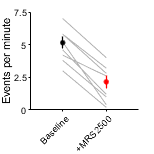

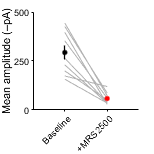

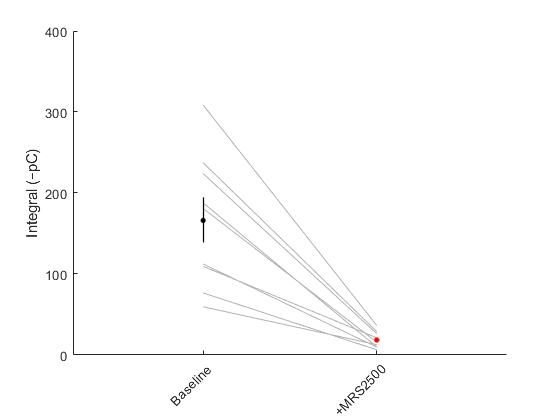

ylim([0 400]);
yticks(0:100:400);
xtickangle(45);

 figh = handleTheSubplot({h, h1, h2}, [1 3]);

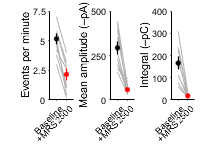

 figQuality(gcf,gca,[2.25 1.5])
 export_fig('.\EPS Panels\RT_summary_stats.eps')



%%original version with PPADS comparison
% dim = [1.6 1.6];
% h = compare3P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),conditions,'Events Per Minute',dim,[5 12]);
% ylim([0 7.5]);
% yticks(0:2.5:7.5);
% xtickangle(45);
% 
% 
% h1 = compare3P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),conditions,'Mean Amp (pA)',dim,[5 12]);
% ylim([0 500]);
% yticks(0:250:500);
% xtickangle(45);
% 
% 
% h2 = compare3P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),conditions,'Charge Transfer (-pA*s)',dim,[5 12]);
% ylim([0 400]);
% yticks(0:100:400);
% xtickangle(45);
% 
% figh = handleTheSubplot({h, h1, h2}, [1 3]);
% figQuality(gcf,gca,[4 1.5])
% export_fig('.\EPS Panels\RT_summary_stats.eps')

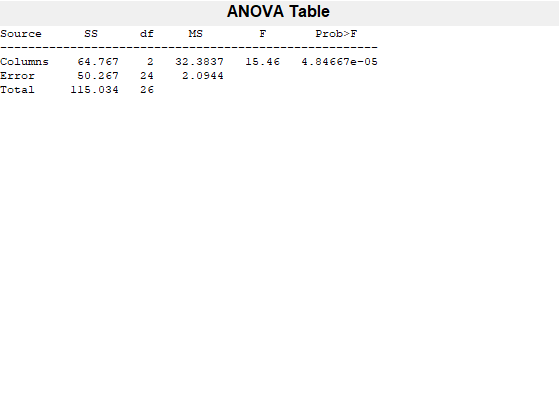

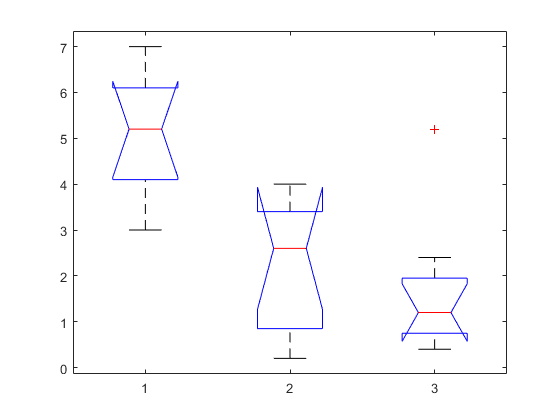

[p,~,stats] = anova1(pkstatBlock);

[c] = multcompare(stats,'display','off')

c =     1.0000    2.0000    1.2963    3.0000    4.7037    0.0005
    1.0000    3.0000    1.8074    3.5111    5.2148    0.0001
    2.0000    3.0000   -1.1926    0.5111    2.2148    0.7370


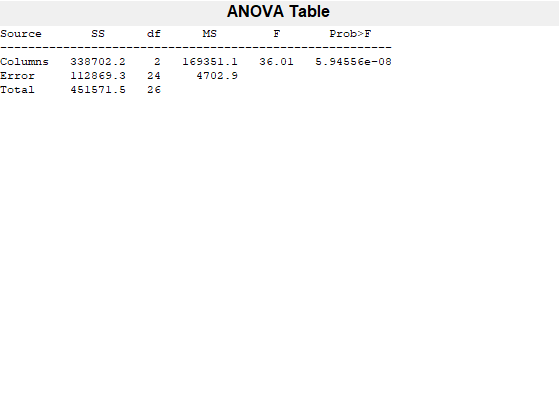

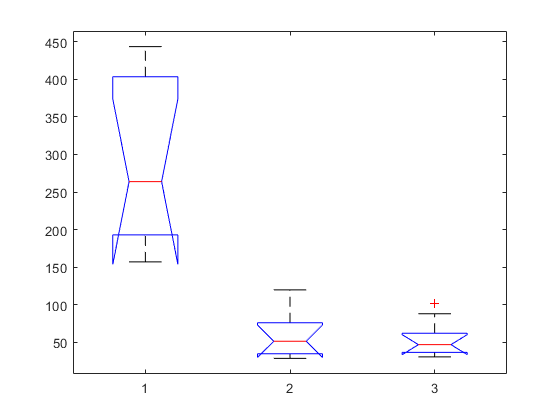


[p,~,stats] = anova1(ampstatBlock);

[c1] = multcompare(stats,'display','off')

c1 =     1.0000    2.0000  154.3420  235.0738  315.8056    0.0000
    1.0000    3.0000  159.3025  240.0343  320.7661    0.0000
    2.0000    3.0000  -75.7713    4.9605   85.6923    0.9871


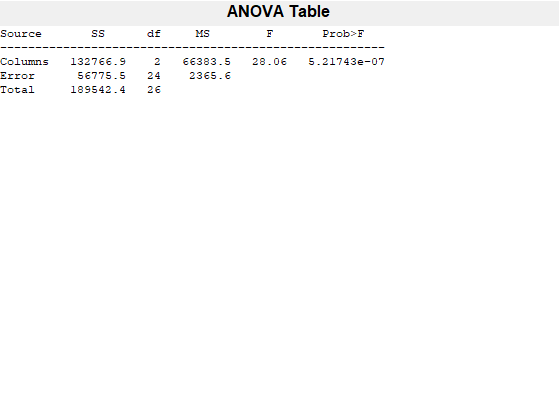

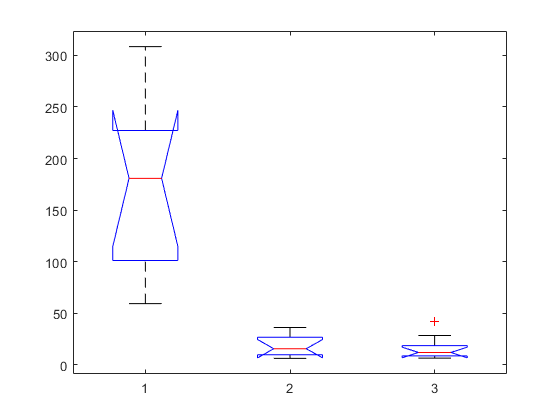


[p,~,stats] = anova1(intstatBlock);

[c2] = multcompare(stats,'display','off')

c2 =     1.0000    2.0000   90.4019  147.6600  204.9182    0.0000
    1.0000    3.0000   92.5666  149.8248  207.0829    0.0000
    2.0000    3.0000  -55.0934    2.1648   59.4229    0.9951


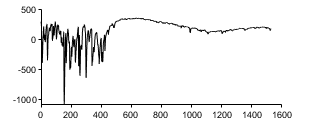

fileList = loadFileList([dname '\*_WT_MRS_PPADS.abf']);
[d,time,SR] = loadPclampData(fileList{9});
figure; plot(time,d,'Color','k');
figQuality(gcf,gca,[3.25 1.25]);
export_fig('.\EPS Panels\example_MRS_PPADS.eps');







%KO Analysis

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 15; %threshold in pA
conditions = {'Baseline','MRS','MRS+SP'};
conditionTimes = [0 300; 540 840; 960 1260];

%%dir 
dname = '.\Data\KO_MRS_PPADS_PT';
folderlist = dir(dname);
folderlist = folderlist(3:end);
analyze = [0 0 1 0];

if exist('cell','var') | exist('cellS','var') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;
        [~,savename,~]=fileparts(fileList{1})
    end
   
    if analyze(4)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    tempCell = cellS(i);
    save([dname '\' folderlist(i).name '\' savename '_KOMRSstats.mat'],'tempCell','-mat')
end

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180802_Cell1\18802002_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB


savename = '18802002_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180802_Cell2\18802018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1327.9 s ~ 22 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 51 MB


savename = '18802018_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1528.8 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 58 MB


savename = '18823011_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1505.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


savename = '18823025_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1501.1 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


savename = '18827018_gfv'

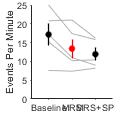

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.2 1.2];
compare3P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),conditions,'Events Per Minute',dim);
ylim([0 25]);
yticks(0:5:25);
export_fig('.\EPS Panels\KOMRSfreq.eps');

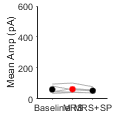


compare3P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),conditions,'Mean Amp (pA)',dim);
ylim([0 600]);
yticks(0:200:600);
export_fig('.\EPS Panels\KOMRSamp.eps');

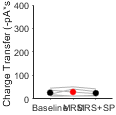



compare3P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),conditions,'Charge Transfer (-pA*s)',dim);
ylim([0 400]);
yticks(0:100:400);
export_fig('.\EPS Panels\KOMRSint.eps');

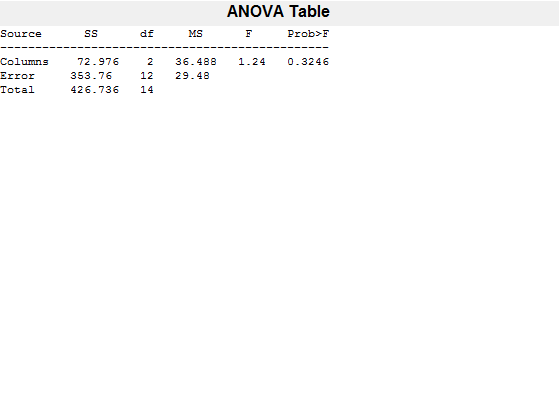

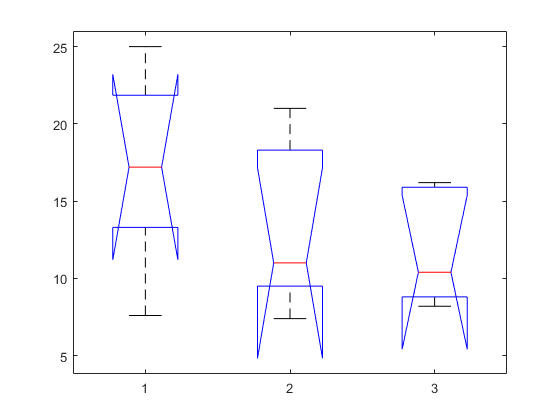

[p,~,stats] = anova1(pkstatBlock);

[c] = multcompare(stats,'display','off')

c =     1.0000    2.0000   -5.4013    3.7600   12.9213    0.5350
    1.0000    3.0000   -3.9213    5.2400   14.4013    0.3140
    2.0000    3.0000   -7.6813    1.4800   10.6413    0.9035


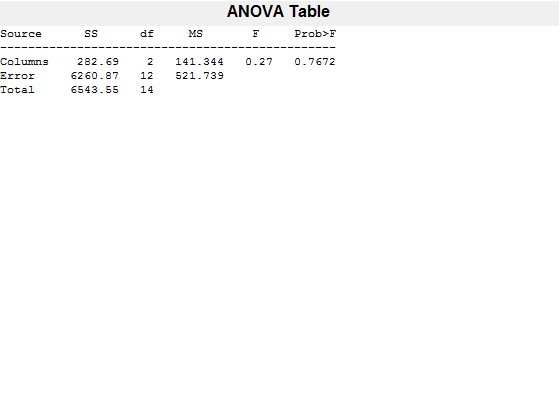

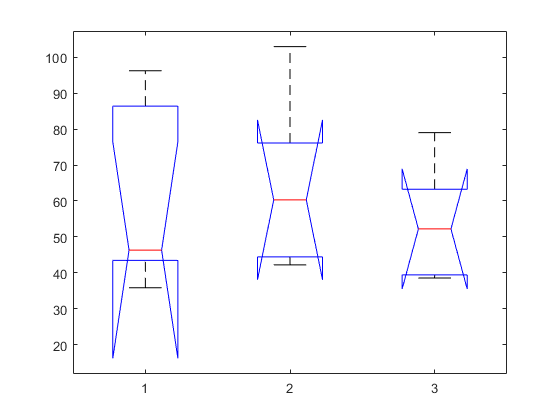


[p,~,stats] = anova1(ampstatBlock);

[c1] = multcompare(stats,'display','off')

c1 =     1.0000    2.0000  -40.6152   -2.0745   36.4663    0.9887
    1.0000    3.0000  -30.5459    7.9949   46.5356    0.8467
    2.0000    3.0000  -28.4714   10.0693   48.6101    0.7697


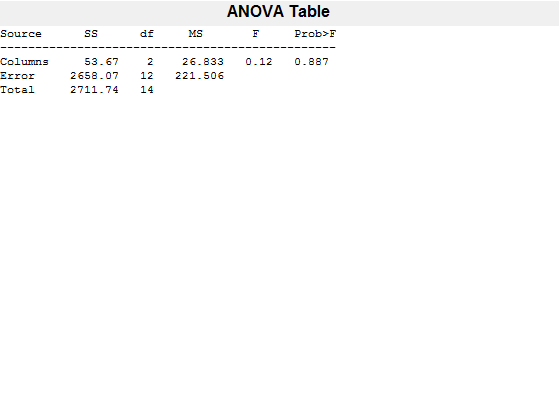

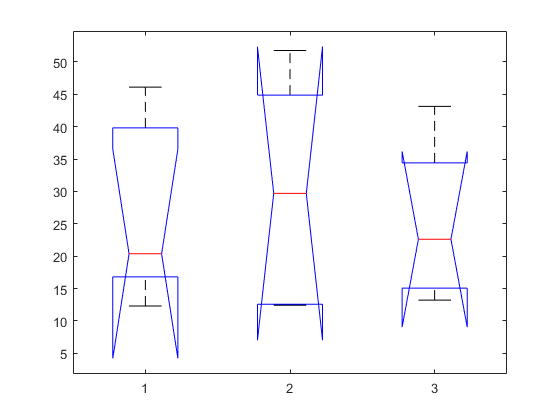


[p,~,stats] = anova1(intstatBlock);

[c2] = multcompare(stats,'display','off')

c2 =     1.0000    2.0000  -27.9702   -2.8579   22.2543    0.9507
    1.0000    3.0000  -23.3831    1.7292   26.8415    0.9816
    2.0000    3.0000  -20.5252    4.5871   29.6994    0.8786


%example trace
file = '.\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf';
[d,time] = loadPclampData(file);

opening .\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1505.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


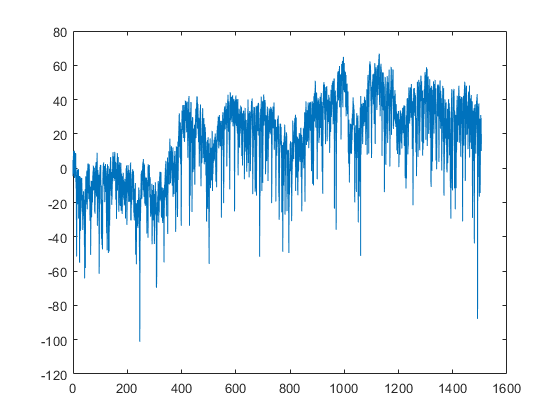

figure;
plot(time,d);

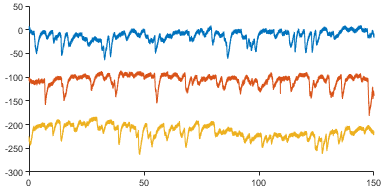


timep = time(time > 0 & time < 150);
p1 = d(time > 10 & time < 160);
p2 = d(time > 540 & time < 690);
p3 = d(time > 1100 & time < 1250);
figure;
plot(timep, p1); hold on;
plot(timep,p2 - 130);
plot(timep,p3 - 250);
figQuality(gcf,gca,[4 2])
export_fig('.\EPS Panels\KOMRSPPADS.eps')